# Part 2

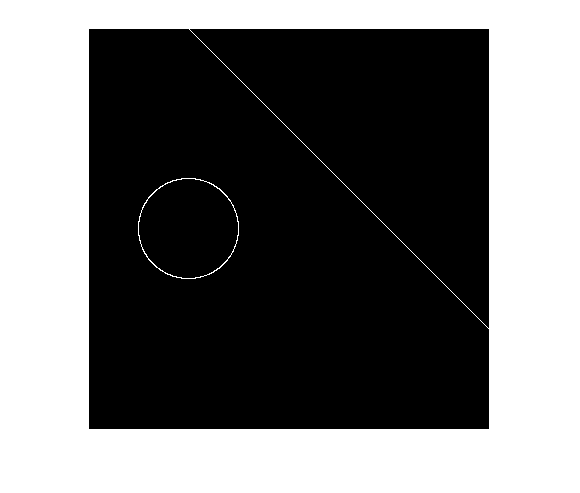


imageSize = 400;

m = 1;
b = -100;

x0 = 100;
y0 = 200;
r = 50;

image = zeros(imageSize);

x = 1:imageSize;

y = m * x + b;

valid = y >= 1 & y <= imageSize;
x_line = x(valid);
y_line = y(valid);

indices_line = sub2ind(size(image), round(y_line), round(x_line));

image(indices_line) = 1;

theta = linspace(0, 2*pi, 1000);

x_circle = x0 + r * cos(theta);
y_circle = y0 + r * sin(theta);

valid = x_circle >= 1 & x_circle <= imageSize & y_circle >= 1 & y_circle <= imageSize;
x_circle = x_circle(valid);
y_circle = y_circle(valid);

indices_circle = sub2ind(size(image), round(y_circle), round(x_circle));

image(indices_circle) = 1;

imshow(image);

imwrite(image, "generatedData.jpg")


## Part 3

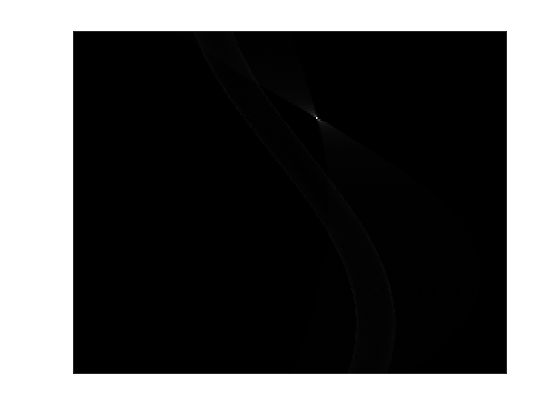



canny_image = edge(image, 'canny');

theta_range = -90:1:89; 
max_rho = round(hypot(size(canny_image, 1), size(canny_image, 2))); %

hough_accumulator = zeros(length(theta_range), 2*max_rho + 1);

[y_coords, x_coords] = find(canny_image); 
num_points = length(x_coords);
for i = 1:num_points
    x = x_coords(i);
    y = y_coords(i);
    for theta_index = 1:length(theta_range)
        theta = deg2rad(theta_range(theta_index));
        rho = round(x*cos(theta) + y*sin(theta));
        rho_index = rho + max_rho + 1;
        hough_accumulator(theta_index, rho_index) = hough_accumulator(theta_index, rho_index) + 1;
    end
end


figure;
imagesc(-max_rho:max_rho, theta_range, hough_accumulator);
colormap(gca, gray);

set(gca, 'XTick', []);
set(gca, 'YTick', []);


[max_val, max_indices] = max(hough_accumulator(:));
[max_theta_index, max_rho_index] = ind2sub(size(hough_accumulator), max_indices);
max_theta = deg2rad(theta_range(max_theta_index));
max_rho = max_rho_index - max_rho - 1;

m = -cos(max_theta) / sin(max_theta);
b = max_rho / sin(max_theta);

fprintf('Maximum value in Hough Transform: %.0f\n', max_val);

Maximum value in Hough Transform: 597


fprintf('Corresponding (theta, rho): (%.2f degrees, %.2f)\n', rad2deg(max_theta), max_rho);

Corresponding (theta, rho): (-45.00 degrees, 69.00)


fprintf('Corresponding (m, b): (%.2f, %.2f)\n', m, b);

Corresponding (m, b): (1.00, -97.58)


## Part 4


min_rad = 10;
max_rad = floor(sqrt(size(image, 1)^2 + size(image, 2)^2));
radii = min_rad:max_rad;

accumulator_3d = zeros(size(image, 1), size(image, 2), max_rad);

for r = radii

    edge_img = edge(image, 'canny');
    
   
    for x = 1:size(image, 2)
        for y = 1:size(image, 1)
            if edge_img(y, x) == 1
                for theta = 0:0.1:2*pi
                    x0 = round(x - r * cos(theta));
                    y0 = round(y - r * sin(theta));
                    if x0 >= 1 && x0 <= size(image, 2) && y0 >= 1 && y0 <= size(image, 1)
                        accumulator_3d(y0, x0, r) = accumulator_3d(y0, x0, r) + 1;
                    end
                end
            end
        end
    end
end


[max_val_3d, max_idx_3d] = max(accumulator_3d(:));
[y0_max, x0_max, r_max] = ind2sub(size(accumulator_3d), max_idx_3d);

fprintf('Maximum value in 3D Hough Transform: %.0f\n', max_val_3d);

Maximum value in 3D Hough Transform: 42


fprintf('Corresponding (x0, y0, r): (%d, %d, %d)\n', x0_max, y0_max, r_max);

Corresponding (x0, y0, r): (100, 200, 48)


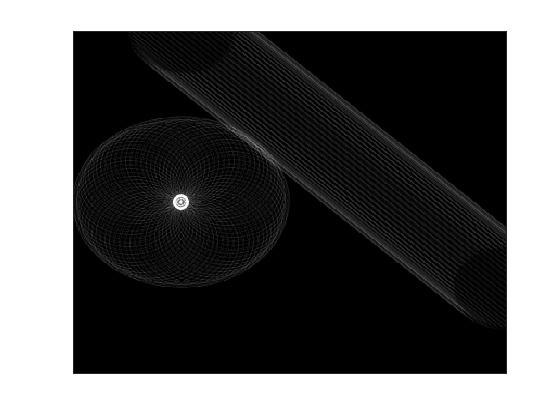


figure;
imagesc(accumulator_3d(:, :, r_max));
colormap(gca, gray); 
caxis([0, max_val_3d * 0.5]); 

set(gca, 'XTick', []);
set(gca, 'YTick', []);

title('');
colorbar('off');
hold on;
plot(x0_max, y0_max, 'wo', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

## Part 5

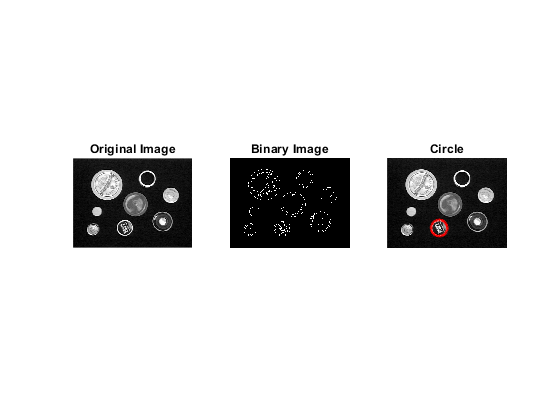

image_gray = imread('circles1.gif');

low_threshold = 0.1;
high_threshold = 0.3; 


canny_image = edge(image_gray, 'canny', [low_threshold, high_threshold]);
figure;

subplot(1, 3, 1);
imshow(image_gray);
title('Original Image');

subplot(1, 3, 2);
imshow(canny_image);
title('Binary Image');

min_rad = 10;
max_rad = floor(sqrt(size(canny_image, 1)^2 + size(canny_image, 2)^2));
radii = min_rad:max_rad;

accumulator_3d = zeros(size(canny_image, 1), size(canny_image, 2), max_rad);

for r = radii
    [y_coords, x_coords] = find(canny_image);
    num_points = length(x_coords);
    for i = 1:num_points
        x = x_coords(i);
        y = y_coords(i);
        for theta = 0:0.1:2*pi
            x0 = round(x - r * cos(theta));
            y0 = round(y - r * sin(theta));
            if x0 >= 1 && x0 <= size(canny_image, 2) && y0 >= 1 && y0 <= size(canny_image, 1)
                accumulator_3d(y0, x0, r) = accumulator_3d(y0, x0, r) + 1;
            end
        end
    end
end

[max_val_3d, max_idx_3d] = max(accumulator_3d(:));
[y0_max, x0_max, r_max] = ind2sub(size(accumulator_3d), max_idx_3d);

subplot(1, 3, 3);
imshow(image_gray);
title('Circle');
hold on;
theta = linspace(0, 2*pi, 1000);
x_circle = x0_max + r_max * cos(theta);
y_circle = y0_max + r_max * sin(theta);
plot(x_circle, y_circle, 'r', 'LineWidth', 2);
hold off;

fprintf('Maximum value in 3D Hough Transform: %.0f\n', max_val_3d);

Maximum value in 3D Hough Transform: 47


fprintf('Corresponding (x0, y0, r): (%d, %d, %d)\n', x0_max, y0_max, r_max);

Corresponding (x0, y0, r): (279, 374, 43)


## Part 6

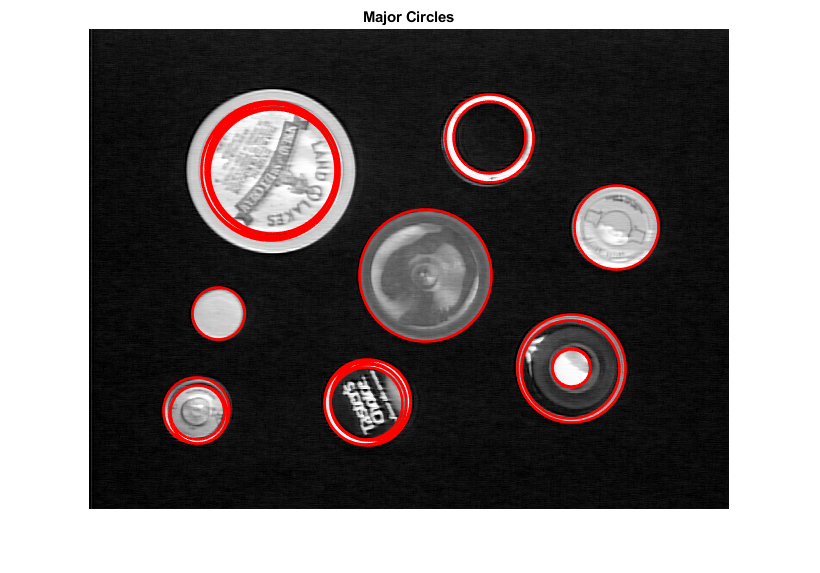

threshold_value = 0.7 * max_val_3d;

filtered_accumulator = accumulator_3d;
filtered_accumulator(filtered_accumulator < threshold_value) = 0;

local_maxima = imregionalmax(filtered_accumulator);

[y0_major, x0_major, r_major] = ind2sub(size(filtered_accumulator), find(local_maxima));

figure;
imshow(image_gray);
title('Major Circles');
hold on;
theta = linspace(0, 2*pi, 1000);

for i = 1:length(x0_major)
    x_circle = x0_major(i) + r_major(i) * cos(theta);
    y_circle = y0_major(i) + r_major(i) * sin(theta);
    plot(x_circle, y_circle, 'r', 'LineWidth', 2);
end
hold off;